clear;clc;

## 读取数据

load("PointOctahedron.mat")
P_bound1 = top_face_transformed(10,:);
P_bound2 = bottom_face_transformed(20,:);
planes = planes';




PAB = [-0.176,-0.06,0.6]';
% P_bound1 = [-0.142,0.47,0.061]*2;
% P_bound2 = [0.57,-0.48,0.138];
phi = pi./6;
phi = pi./2 - phi;
shenglunum = 5;
a = 0.015*ones(1,2*shenglunum);
distanceThreshold = 0.2;


[PlaneParaOut8,TrianglePoints8,MaxDis,distancesFianal] = planefit8(side_faces_transformed1',side_faces_transformed2',side_faces_transformed3',side_faces_transformed4',side_faces_transformed5',side_faces_transformed6',side_faces_transformed7',side_faces_transformed8',P_bound1,P_bound2,0.2);

Isempty FACE2468: 100.000000, 100.000000, 100.000000, 100.000000


## 计算 AB面

% 加 输出   计算 和判断 偏移
Ti = ShengDaoGaoDu(shenglunum);

[PointTable_A_off8,PointTable_B_off8,XieMianPianYi] = Calculate_rectangle_from_vertex8(side_faces_transformed1',side_faces_transformed2',side_faces_transformed3',side_faces_transformed4',side_faces_transformed5',side_faces_transformed6',side_faces_transformed7',side_faces_transformed8',P_bound1,P_bound2,PAB,phi,shenglunum,Ti,a,distanceThreshold)

Isempty FACE2468: 100.000000, 100.000000, 100.000000, 100.000000


PointTable_A_off8 =     0.1685    0.0146   -0.3609    0.0346    0.2900    0.5386    0.5611    0.5611    0.5611    0.4755
   -0.3958   -0.2482   -0.0281    0.1931    0.3407    0.0818   -0.0698   -0.2860   -0.5021   -0.6547
    0.1082    0.1936    0.3210    0.4489    0.5343    0.9795    0.8918    0.7668    0.6417    0.5534


PointTable_B_off8 =     0.1685    0.0146   -0.3609    0.0346    0.2900    0.5386    0.5611    0.5611    0.5611    0.4755
   -0.6537   -0.5061   -0.2860   -0.0648    0.0827    0.3397    0.1881   -0.0281   -0.2442   -0.3968
    0.5540    0.6394    0.7668    0.8947    0.9801    0.5337    0.4460    0.3210    0.1959    0.1077


XieMianPianYi =     0.0135    0.0135         0    0.0225    0.0225    0.0135         0         0         0    0.0224


## 验证

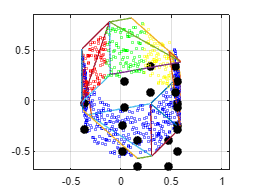

figure
hold on 
box on
grid on
axis equal
scatter3(side_faces_transformed1(:,1),side_faces_transformed1(:,2),side_faces_transformed1(:,3),5,'yellow')
scatter3(side_faces_transformed2(:,1),side_faces_transformed2(:,2),side_faces_transformed2(:,3),5,'green')
scatter3(side_faces_transformed3(:,1),side_faces_transformed3(:,2),side_faces_transformed3(:,3),5,'red')
scatter3(side_faces_transformed4(:,1),side_faces_transformed4(:,2),side_faces_transformed4(:,3),5,'blue')
scatter3(side_faces_transformed5(:,1),side_faces_transformed5(:,2),side_faces_transformed5(:,3),5,'blue')
scatter3(side_faces_transformed6(:,1),side_faces_transformed6(:,2),side_faces_transformed6(:,3),5,'blue')
scatter3(side_faces_transformed7(:,1),side_faces_transformed7(:,2),side_faces_transformed7(:,3),5,'blue')
scatter3(side_faces_transformed8(:,1),side_faces_transformed8(:,2),side_faces_transformed8(:,3),5,'blue')
for i =1:16
    idt = [(i-1)*3+1:i*3,(i-1)*3+1];
    PointTri = TrianglePoints8(:,idt);
    plot3(PointTri(1,:),PointTri(2,:),PointTri(3,:));
end

scatter3(PointTable_A_off8(1,:),PointTable_A_off8(2,:),PointTable_A_off8(3,:),50,'filled','black')
scatter3(PointTable_B_off8(1,:),PointTable_B_off8(2,:),PointTable_B_off8(3,:),50,'filled','black')

## 构建复测数据

% 构建测点输入
PointIn = [];
for i = 1:shenglunum
    temp = [PointTable_A_off8(:,i),PointTable_A_off8(:,end+1-i)];
    PointIn = [PointIn,temp];
end

% 计算参数（用于输入）
[PlaneParaOut,TrianglePoints4,~,~] = planefit4(side_faces_transformed1',side_faces_transformed3',side_faces_transformed5',side_faces_transformed7',P_bound1,P_bound2,distanceThreshold);
[Pin,Pout,UPP,b,h,~,Tao,~] = Calculate_rectangle_from_vertex(TrianglePoints4);




## 计算距离

LenDaoJiao = 0.2*ones(1,8);
[Distance,theta,LTPY,TiC,Wquanzhong3,Wquanzhong4]=JuXingFuCe(PointIn,shenglunum,Pin,Tao,h,PlaneParaOut,LenDaoJiao)